% =======================================================================
%
% Script pour le TP01 - Random Variables
%
% =======================================================================

close all

## 1. HISTOGRAMS AND CORRELATION

## 1.1 Analysis of 1D signals

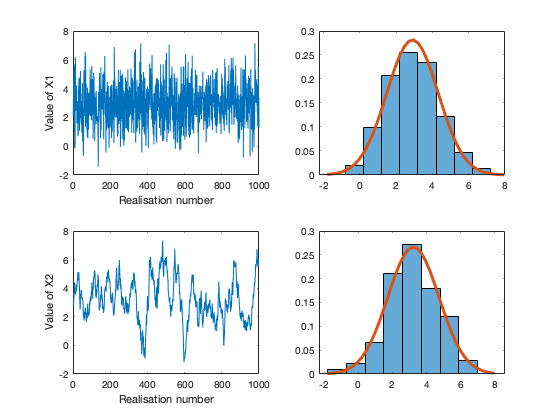

% chargement du fichier RandomSamples.mat
load RandomSamples ;
X = R_X1 ;
Y = R_X2 ;

% parametres utiles
N    = length(X) ; % taille des echantillons
bins = 9 ;         % nombre de bins des histogrammes

% calcul des moyennes et variances
mx = mean(X); sigx = std(X) ;
my = mean(Y); sigy = std(Y) ;

% generation des histogrammes normalisés (pour obtenir des pdf)
figure(1), hold on
subplot(221) ;
plot(X) ;
xlabel('Realisation number'); ylabel('Value of X1');
subplot(222) ;
hx = histogram(X,bins,'normalization','pdf') ;
subplot(223) ; 
plot(Y) ;
xlabel('Realisation number'); ylabel('Value of X2');
subplot(224) ;
hy = histogram(Y,bins,'normalization','pdf') ;

% generation d'un profil gaussien pour chaque VA
ax = hx.BinEdges ;
ay = hy.BinEdges ;
axx = interp(ax,4);
ayy = interp(ax,4);
Gx = 1/(sqrt(2*pi)*sigx)*exp(-0.5*((axx-mx)/sigx).^2);
Gy = 1/(sqrt(2*pi)*sigy)*exp(-0.5*((ayy-my)/sigy).^2);

% on superpose les courbes théoriques sur les histogrammes
figure(1)
subplot(222) ; hold on ;
plot(axx,Gx,'LineWidth',3)
subplot(224) ; hold on ;
plot(ayy,Gy,'LineWidth',3)

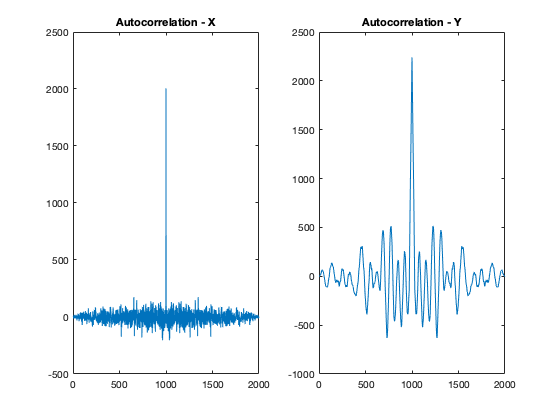


% bruit blanc ? on calcul les autorcorrelation
CX = xcorr(X-mx) ;
CY = xcorr(Y-my) ;

% on affiche les autocorrelations
figure;
subplot(121), plot(CX) ; title('Autocorrelation - X');
subplot(122), plot(CY) ; title('Autocorrelation - Y');

% on remarque que CX est un dirac ce qui est la marque d'un bruit blanc
% (bruit delta-corrélé). Ce n'est pas le cas pour CY.


## 1.2 Study of 2D data

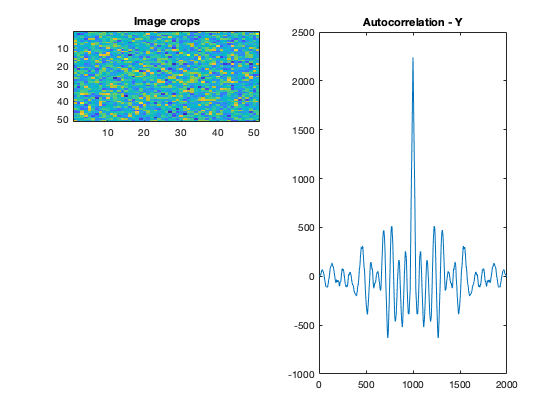

% on genere les données
load NoisyImage ;
I0 = NoisyImage ;
I0 = I0./max(max(I0));

% on "crop" l'image pour les zones 1 et 2
I1 = imcrop(I0, [1 1 50 50 ]) ;
I2 = imcrop(I0, [110 70 30 30 ]) ;
I3 = imcrop(I0, [130 170 70 70 ]) ;

% on creer l'aire la plus grande possible pour la 3eme zone
c = [168 132 131 254 254] ;
r = [131 167 254 254 226] ;
BW = roipoly(I0,c,r);
I3bis = BW.*I0 ;

% on cree les vecteurs pour les histogrammes associés
I1h = I1(:) ;
I2h = I2(:) ;
I3h = I3bis(I3bis~=0) ; % pour l'histogramme on prend les pixels non nuls de la zone 3
bins = 50 ;

% generation des histogrammes normalisés (pour obtenir des pdf)
figure(2)
subplot(321) ;
imagesc(I1) ; title('Image crops') ; 

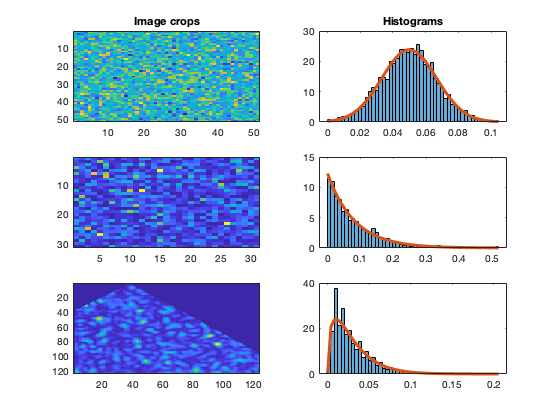

subplot(322) ;
h1 = histogram(I1h,bins,'normalization','pdf') ; title('Histograms') ; 
subplot(323) ; 
imagesc(I2) ; 
subplot(324) ;
h2 = histogram(I2h,bins,'normalization','pdf') ;
subplot(325) ; 
imagesc(I3bis(min(r):max(r),min(c):max(c))) ; 
subplot(326) ;
h3 = histogram(I3h,bins,'normalization','pdf') ;

% on calcule les pdf théoriques
a1 = h1.BinEdges ;
var1 = var(I1h) ; mu1 = mean(I1h) ;
pdf1 = 1./sqrt(2*pi*var1).*exp(-1/(2*var1).*(a1-mu1).^2) ;
a2 = h2.BinEdges ;
mu2 = mean(I2h) ;
pdf2 = exp(-a2./mu2)./mu2 ;
a3 = h3.BinEdges ;
mu3 = mean(I3h) ;
pdf3 = gampdf(a3,1.5,mu3/1.5) ;

% on les superpose aux histogrammes
figure(2)
subplot(322) ; hold on ;
plot(a1,pdf1,'LineWidth',3)
subplot(324) ; hold on ;
plot(a2,pdf2,'LineWidth',3)
subplot(326) ; hold on ;
plot(a3,pdf3,'LineWidth',3)

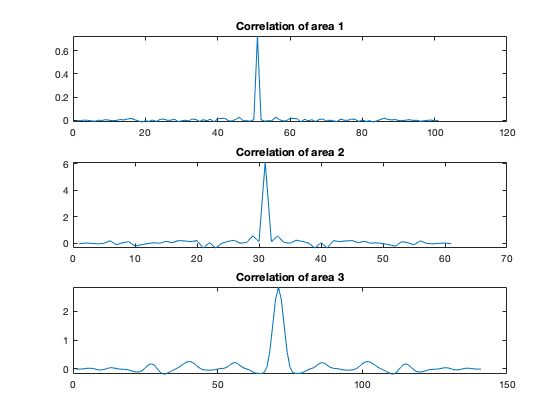


% bruit blanc?
C1 = xcorr2(I1-mu1) ;
C2 = xcorr2(I2-mu2) ;
C3 = xcorr2(I3-mu3) ;

% on affiche les profils des autocorellations
figure;
subplot(311); plot(C1(round(end/2),:)); title('Correlation of area 1'); 
subplot(312); plot(C2(round(end/2),:)); title('Correlation of area 2'); 
subplot(313); plot(C3(round(end/2),:)); title('Correlation of area 3');

% on constate que les bruits des zones 1 et 2 sont biens des bruits blancs
% mais pas celui de la 3.

## 2. FIRST EXAMPLES. VARIANCE OF AN ESTIMATOR.

## 2.1. Estimator of the mean of a Gaussian sample

clear N K mu sig ;

% parametres
N   = 10 ;
K   = 1000 ;
mu  = 3 ;    % moyenne des realisations
sig = 2 ;    % ecart-type

% generation des echantillons
R_Xg = sig*randn(K,N)+mu ;

% calcul des moyenne et variance
m_emp = mean(R_Xg,2);
bias = m_emp-mu;
var_mu_emp = var(m_emp);
var_true = sig^2/N;

% affichage des resultats
fprintf(1,' Le biais (moyen) est de %f et la variance de l''estimateur de %f \n', mean(bias),var_mu_emp);

 Le biais (moyen) est de 0.003319 et la variance de l'estimateur de 0.394951 


fprintf(1,' Le biais et la variance attenuds sont de %f et %f respectivement \n', 0, var_true);

 Le biais et la variance attenuds sont de 0.000000 et 0.400000 respectivement 


fprintf(1,'\n');


## 2.2. Estimator of the mean of an exponential sample

clear N K m ;

% parametres
N = 10 ;
K = 10000 ;
m = 3 ;

% generation des echantillons
R_Xe = randexp(K,N,m) ;

% calcul des moyenne et variance
m_emp = mean(R_Xe,2);
bias = m_emp-m;
var_m_emp = var(m_emp);
var_true = m^2/N ;

% affichage des resultats
fprintf(1,' Le biais (moyen) est de %f et la variance de l''estimateur de %f \n', mean(bias),var_m_emp);

 Le biais (moyen) est de -0.000023 et la variance de l'estimateur de 0.889738 


fprintf(1,' Le biais et la variance attenuds sont de %f et %f respectivement \n', 0, var_true);

 Le biais et la variance attenuds sont de 0.000000 et 0.900000 respectivement 


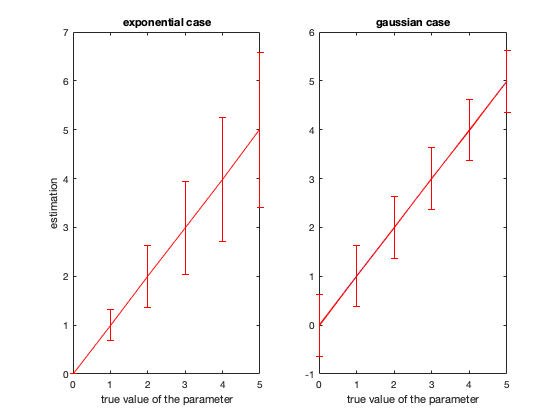

fprintf(1,'\n');

% estimation pour plusieurs valeurs de m
moy = 0:5 ;
moy_emp = NaN(size(moy));
err = NaN(size(moy));
err_exp = err ;
for k=moy
    R_Xe  = randexp(K,N,k) ;
    moy_emp(k+1) = mean(R_Xe(:));
    err(k+1) = k/sqrt(N ); % ecart-type
    err_exp(k+1) = sqrt(var(mean(R_Xe,2))) ; 
end
figure;hold on;
subplot(121)
plot(moy,moy_emp,'b',moy,moy,'r');
errorbar(moy,moy_emp,err_exp,'b')
errorbar(moy,moy_emp,err,'r')
ylabel('estimation');xlabel('true value of the parameter');
title('exponential case')

% meme courbe dans le cas gaussien
moy = 0:5 ;
sig = 2 ;
moy_emp = NaN(size(moy));
err = NaN(size(moy));
err_exp = err ;
for k=moy
    R_Xg  = sig*randn(K,N)+k ;
    moy_emp(k+1) = mean(R_Xg(:));
    err(k+1) = sig/sqrt(N) ;
    err_exp(k+1) = sqrt(var(mean(R_Xg,2))) ; 
end
subplot(122)
plot(moy,moy_emp,'b',moy,moy,'r');
hold on
errorbar(moy,moy_emp,err_exp,'b')
errorbar(moy,moy_emp,err,'r')
xlabel('true value of the parameter');
title('gaussian case')

## 3.2 Estimation of the location parameter of a Cauchy random variable


clear N K a ;

% parametres
N = 1000 ;
K = 1000 ;
a = 3 ;

% generation des echantillons
R_Xc = randcauchy(K,N,a) ;

% calcul des moyenne et variance
moy_emp = mean(mean(R_Xc));
med_emp = mean(median(R_Xc));
med_var = var(median(R_Xc))

% affichage des resultats
fprintf(1,' La moyenne est de %f et la médiane de %f \n', moy_emp, med_emp);
fprintf(1,' La mediane attendue est de %f \n', a);
fprintf(1,'\n');
